## Extract App Graphs using Map Reduce

An optimized version of muBench Alibaba Example Script, utilizing parallelism to handle larger input data

[https://de.mathworks.com/help/matlab/ref/mapreduce.html](https://de.mathworks.com/help/matlab/ref/mapreduce.html)

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

## Actual Script below

### Prepare selected columns

We may not care about certain columns, once we fully understand the trace data.

[trace_header, trace_formats, trace_vartypes] = constants();
ignore_columns = ["response_time"];
used_col_idx = ~ismember(trace_header, ignore_columns);
trace_selected_cols = trace_header(used_col_idx);
trace_selected_vartypes = trace_vartypes(used_col_idx);
trace_selected_formats = trace_formats(used_col_idx);

clear trace_formats;
clear trace_vartypes;
clear ignore_columns;

### Create Datastore

Read in .csv and create a datastore that can be used with mapreduce.

[trace_location, trace_header_lines, ~, ~, ~, ~, ~] = config();
ds = tabularTextDatastore(trace_location, "NumHeaderLines", trace_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", trace_header, ...
    "SelectedFormats", trace_selected_formats, ...
    "SelectedVariableNames", trace_selected_cols);

Error using tabularTextDatastore (line 157)
Cannot find files or folders matching: '../../traces/alibaba/2022-ms/CallGraph/CallGraph_0.csv'.


clear trace_location;
clear trace_header_lines;
clear trace_selected_formats;

prev_ds = copy(ds);
reset(prev_ds);
prev_ds.ReadSize = 100;
read(prev_ds)
clear prev_ds;

### Map Reduce to find valid trace ids

This section filters out invalid traces

Invalidation Criteria:

- interface, upstream_ms or downstream_ms is "UNKNOWN" or "UNAVAILABLE"

- The rpc_id parent of an entry of one trace_id is not present

- An entry of one trace_id is not connected to the "USER" upstream entry

col_idx_trace_id = strcmp(trace_header, "trace_id") > 0;
% wrap mapper function to pass variable context
mapFunc = @(a, b, c)trace_mapper(a, b, c, col_idx_trace_id);
% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_selected_vartypes)], 'VariableTypes',trace_selected_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)trace_reducer(a, b, c, empty_table);
tic
trace_ds = mapreduce(ds, mapFunc, reduceFunc, 'OutputFolder', './results');
toc
clear empty_table;
clear col_idx_trace_id;
clear mapFunc;
clear reduceFunc;

### Data Example

Optional: Gives a preview of the data.

prev_trace_ds = copy(trace_ds);
reset(prev_trace_ds);
prev_trace_ds.ReadSize = 10;
prev_trace_data = read(prev_trace_ds);
prev_trace_data.Value{:,1}

clear prev_trace_ds;
clear prev_trace_data;

### Map Reduce to services

This section filters out invalid traces and stores the resulting trace entries grouped by service

col_idx_service = strcmp(trace_header, "service") > 0;
% wrap mapper function to pass variable context
mapFunc = @(a, b, c)service_mapper(a, b, c, col_idx_service);
% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_selected_vartypes)], 'VariableTypes',trace_selected_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)service_reducer(a, b, c, empty_table);
tic
service_ds = mapreduce(trace_ds, mapFunc, reduceFunc, 'OutputFolder', './results');
toc
clear empty_table;
clear col_idx_service;
clear mapFunc;
clear reduceFunc;

### Data Example

Optional: Gives a preview of the data.

prev_svc_ds = copy(service_ds);
reset(prev_svc_ds);
prev_svc_ds.ReadSize = 10;
prev_svc_data = read(prev_svc_ds);
prev_svc_data.Value{:,1}

clear prev_svc_ds;
clear prev_svc_data;

### Service Graphs

Create directed graphs from the trace entries related to a specific service.

tic
service_graph_ds = mapreduce(service_ds, @service_graph_mapper, @service_graph_reducer, 'OutputFolder', './results');
toc

### Port dataformat

From MapReduce KeyValueDatastore output to serial processing

(we leave the map-reduce environment and process classically)

service_graphs = readall(service_graph_ds);

### Prepare Input

Prepare input data to be a nicely accessible table

% Flatten service_graphs.Value into a table with 3 columns
value_as_table = cell2table(service_graphs.Value);
flattened_values = cell2table(value_as_table{:,1});
services = [service_graphs.Key flattened_values];
% Label Columns
services.Properties.VariableNames(1) = "service_id";
services.Properties.VariableNames(2) = "graph";
services.Properties.VariableNames(3) = "possible_node_names";
services.Properties.VariableNames(4) = "ms_count";
services.Properties.VariableNames(5) = "max_depth";
services.Properties.VariableNames(6) = "trace_count";


clear value_as_table;
clear flattened_values;

clear service_graphs;

heatmap(services,"max_depth","ms_count","ColorScaling","log");

### Filter Input

About 31500 of the ~36000 services only have a ms_count of 1 (monoliths).

To reduce the computing time for clustering and provide proper scales we split up the input data into 

- monoliths (USER calls Service and done -> ms_count == 1)

- microservices (ms_count > 1)

monolith_idx = services.ms_count < 2;
monolith_design = services(monolith_idx,:);
microservice_design = services(~monolith_idx,:);
clear monolith_idx;

### Manual inspection of microservices

Heatmap of microservices service_count and max depths of their call graph

figure;
heatmap(microservice_design,"max_depth","ms_count","ColorScaling","log");

Plot distribution grouped by ms_count. (How many 

byMSCount = groupsummary(microservice_design,"ms_count")
bar(byMSCount.ms_count, byMSCount.GroupCount);
title("Services by involved service count");
yscale log;
ylabel("Service Count");
xlabel("# of involved services");
clear byMSCount;

### Create X clusters

We inspect the found service graphs for similarity and cluster them into N+1 parts.

We will treat all monoliths as one cluster and the microservices share the other N clusters.

### Calculate service similarities

Takes a long time

tic
microservice_design_similarity_matrix = service_similarity(microservice_design);
toc

% Security copy to file
save('ms_similarities.mat', 'microservice_design_similarity_matrix', '-v7.3');

### Binary similarity matrix

[~, ~, ~, ~, ~, similarity_threshold, ~, ~] = config();
logical = microservice_design_similarity_matrix > similarity_threshold;
binary_similarity_matrix = single(logical);
fprintf("Applying threshold of %f", similarity_threshold);

Applying threshold of 0.900000


% We do not clear the 'microservice_design_similarity_matrix' as it takes a long
% time to re-generate and is used to experiment with several threshold
% values further down...
clear logical;
clear similarity_threshold;

### OPTIONAL: Find optimal cluster count

For pure reproduction this step could be skipped, as it is time intensive. For further calculations the ms_cluster_count from the config file is used. 

If you want to calculate your own ideal cluster number make sure to add it in the config.m file!

% Test for each cluster count in the defined range
evaluation_range = 2:50;

% Clustering method to use
clusterfunc=@(X,K)(spectralcluster(X,K));

tic
% Runs the specified clustering method once for each item (K) of
% 'evaluation_range' and returns the K for the best achieved results
k_opt=evalclusters(binary_similarity_matrix,clusterfunc,'CalinskiHarabasz','klist',evaluation_range);
toc

% extrace the optimal amount of clusters.
ideal_cluster_count = k_opt.OptimalK;
fprintf("Ideal cluster count is: %d", ideal_cluster_count);
disp("!!IF YOU WANT TO USE THIS VALUE - UPDATE YOUR 'config.m'!!!")
clear clusterfunc;
clear k_opt;

#### Cluster microservices

The algorithm uses a 'random_walk' which sometimes fails to complete. Try re-running this step when that happens.

[~, ~, ~, ~, ~, ~, ms_cluster_count, ~] = config();
rng(161,"philox");
tic
[microservice_clusters] = service_clustering(microservice_design,binary_similarity_matrix,ms_cluster_count);

Unrecognized function or variable 'microservice_design'.

toc
clear limit;
clear microservices;
clear binary_similarity_matrix;

#### Prepare monolith data

% Create a cluster ID for the monoliths
monolith_cluster_id = ms_cluster_count + 1;

% Create monolith clustered table by appending the id to all entries
monolith_cluster_nr = zeros(height(monolith_design),1) + monolith_cluster_id;
monolith_clusters = [monolith_design table(monolith_cluster_nr)];

% Label column of table
monolith_clusters.Properties.VariableNames(width(monolith_clusters)) = "cluster";

clear monolith_cluster_id;
clear monolith_cluster_nr;

### Combine microservices and monolith clusters

service_clusters = [microservice_clusters; monolith_clusters];

### Inspect depth and ms count by cluster

Can be used to get a first manual sanity check on the output.

meansByCluster = groupsummary(service_clusters,"cluster","mean",["max_depth","ms_count"])

meansByCluster = 35×4 table
    cluster    GroupCount    mean_max_depth    mean_ms_count
    _______    __________    ______________    _____________

       1          487                 2                4    
       2           88                 1                2    
       3           24                 3                6    
       4          433            2.9815           3.9815    
       5           64                 2                4    
       6           17            2.8235           5.4118    
       7           14                 2                6    
       8           22                 3                3    
       9           12                 1                4    
      10           28                 1                3    
      11           41                 3           4.9024    
      12          145                 2   

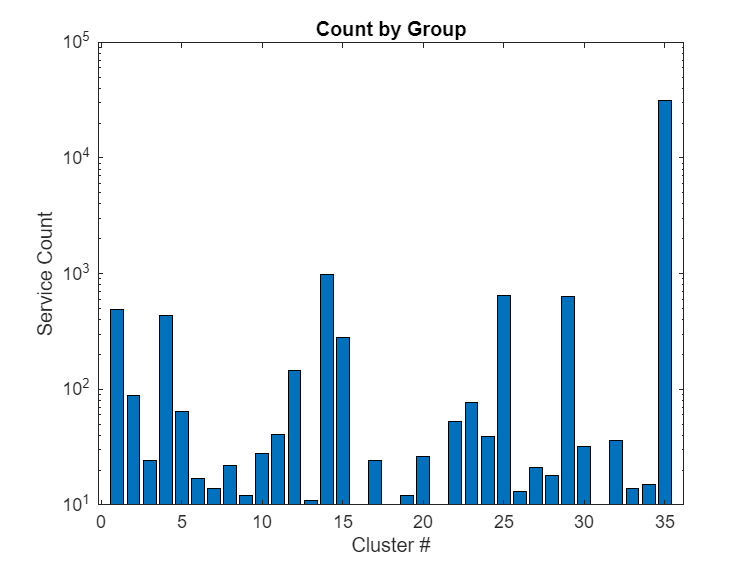

figure;
bar(meansByCluster.cluster, meansByCluster.GroupCount);
title("Count by Group");
yscale log;
ylabel("Service Count");
xlabel("Cluster #");


clear meansByCluster;

### Sample services

Extract a sample of % services, as we do not want to deploy ~38k services.

Workload with muBench is mainly generated through requests, so we do not only have a choice of "which services", but also "how many requests for the selected services"

[~, ~, ~, ~, ~, ~, ~, sampling_factor] = config();
fprintf("Sampling factor: %f", sampling_factor);

Sampling factor: 0.010000

[service_samples] = service_sampling(service_clusters, sampling_factor)

service_samples = 382×9 table
      service_id           graph        possible_node_names    ms_count    max_depth    trace_count    cluster    service_cluster_share    trace_factor
    _______________    _____________    ___________________    ________    _________    ___________    _______    _____________________    ____________

    {'S_80522247' }    {1×1 digraph}        {1×1 cell}            4            2            384           1               0.96482            0.067312  
    {'S_106901300'}    {1×1 digraph}        {1×1 cell}            4            2              6           1              0.015075            0.067312  
    {'S_34456810' }    {1×1 digraph}        {1×1 cell} 

clear sampling_factor;

### Manual Sanity Checks on sampled data

% select all MS graphs
ms_only = service_samples(service_samples.cluster <= ms_cluster_count,["service_id", "cluster", "ms_count", "max_depth", "trace_factor", "trace_count", "service_cluster_share", "graph"])
clear ms_only;

### Plot call graphs

Manual sanity check to validate clustering led to reasonable results.

Skips structurally identical graphs within the groups.

% Collect all plots to be drawn and their title
plots = cell(0,2);

% include the monolith cluster
cluster_count = ms_cluster_count + 1;
for c=1:cluster_count
    fprintf("\nGroup %d: Plotting graphs ...", c);
    group = service_samples(service_samples.cluster == c,:);
    % Save graphs we already know for this group
    known_graphs = cell(0);
    for i=1:height(group)
        g = group.graph{i};
        % Check if we already drew an isomorphic graph
        draw = true;
        for k=1:height(known_graphs)
            if isisomorphic(known_graphs{k}, g)
                draw = false;
                fprintf("skipping a known graph ...");
                break;
            end
        end
        if ~draw
            % is already known, moving on
            continue;
        end
        % Add to known graphs
        known_graphs = [known_graphs; {g}];
        % Create title with service_id including group
        t = "[" + c + "]";
        % Add to global plots
        plots = [plots; {t g}];
    end
end


Group 1: Plotting graphs ...

skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...


Group 2: Plotting graphs ...
Group 3: Plotting graphs ...
Group 4: Plotting graphs ...

skipping a known graph ...skipping a known graph ...skipping a known graph ...


Group 5: Plotting graphs ...
Group 6: Plotting graphs ...
Group 7: Plotting graphs ...
Group 8: Plotting graphs ...
Group 9: Plotting graphs ...
Group 10: Plotting graphs ...
Group 11: Plotting graphs ...
Group 12: Plotting graphs ...

skipping a known graph ...


Group 13: Plotting graphs ...
Group 14: Plotting graphs ...

skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...


Group 15: Plotting graphs ...

skipping a known graph ...skipping a known graph ...


Group 16: Plotting graphs ...
Group 17: Plotting graphs ...
Group 18: Plotting graphs ...
Group 19: Plotting graphs ...
Group 20: Plotting graphs ...
Group 21: Plotting graphs ...
Group 22: Plotting graphs ...
Group 23: Plotting graphs ...
Group 24: Plotting graphs ...
Group 25: Plotting graphs ...
Group 26: Plotting graphs ...
Group 27: Plotting graphs ...
Group 28: Plotting graphs ...
Group 29: Plotting graphs ...

skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...


Group 30: Plotting graphs ...
Group 31: Plotting graphs ...
Group 32: Plotting graphs ...
Group 33: Plotting graphs ...
Group 34: Plotting graphs ...
Group 35: Plotting graphs ...

skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a known graph ...skipping a k

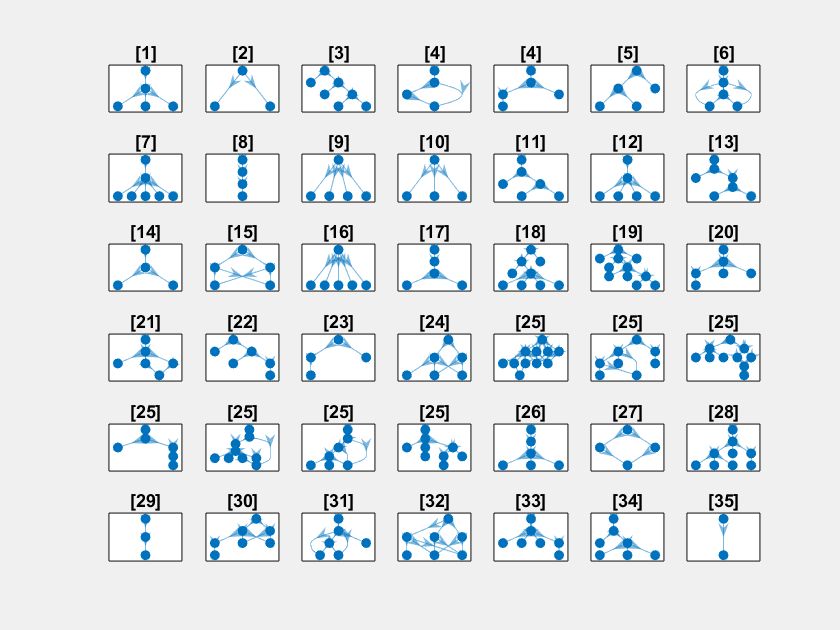

plot_count = height(plots);
% plot_count = 9;
% Calculate grid sizes
subplot_cols = ceil(sqrt(plot_count));
subplot_rows = ceil(plot_count / subplot_cols);

% Create new figure to force the plot into a new popup window
f = figure();
set(f,'Visible','off');
for i=1:plot_count
    g = plots{i,2};
    subplot(subplot_rows,subplot_cols,i);
    plot(g, "NodeLabel", strings(height(g.Nodes.Name), 1));
    title(plots{i,1});
end
set(f,'Visible','on');


clear known_graphs;
clear draw;
clear g;
clear t;
clear c;
clear i;
clear k;
clear group;
clear plots;
clear plot_count;
clear subplot_cols;
clear subplot_rows;

### RAW SAVE to file system

Loading the save could be used to change export format later-on.

save('extracted_samples.mat', 'service_samples');

### Export

Create output table

% Get ms names of services.graphs
ms_names_cell = rowfun(@getGraphMsNames, ...
                   service_samples, ...
                   "InputVariables","graph", ...
                   "OutputVariableNames","ms_names", ...
                   "OutputFormat", "cell");
service_id = string(service_samples.service_id);
export = [table(service_id) service_samples(:,["cluster", "trace_factor"]) ms_names_cell];
export.Properties.VariableNames(4) = "involved_ms";
disp(export);

     service_id      cluster    trace_factor                                                                         involved_ms                                                                     
    _____________    _______    ____________    _____________________________________________________________________________________________________________________________________________________

    "S_80522247"        1         0.067312      {["MS_25004"    "MS_27421"    "MS_68906"    "MS_8237"    "USER"                                                                                    ]}
    "S_106901300"       1         0.067312      {["MS_27421"    "MS_2971"    "MS_37691"    "MS_66711"    "USER"                                                                                    ]}
    "S_34456810"        1         0.067312      {["MS_27421"    "MS_297

clear ms_names_cell;

Save export

save('../sampled_services_export.mat', 'export');